q1 sub1

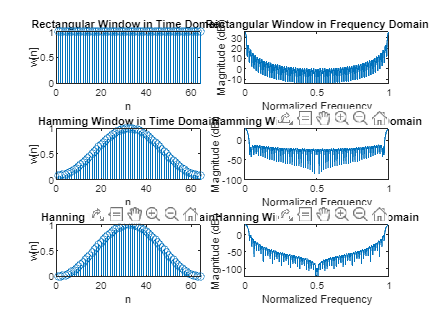

% window length
N = 64;

rectangular_window = rectwin(N);
hamming_window = hamming(N);
hanning_window = hann(N);

%frequency responses
rectangular_freq = abs(fft(rectangular_window, 1024));
hamming_freq = abs(fft(hamming_window, 1024));
hanning_freq = abs(fft(hanning_window, 1024));

f = (0:1023)/1024;

% Plot the time responses
figure;
subplot(3,2,1);
stem(rectangular_window);
title('Rectangular Window in Time Domain');
xlabel('n');
ylabel('w[n]');

subplot(3,2,3);
stem(hamming_window);
title('Hamming Window in Time Domain');
xlabel('n');
ylabel('w[n]');

subplot(3,2,5);
stem(hanning_window);
title('Hanning Window in Time Domain');
xlabel('n');
ylabel('w[n]');

% Plot the frequency responses
subplot(3,2,2);
plot(f, 20*log10(rectangular_freq));
title('Rectangular Window in Frequency Domain');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');

subplot(3,2,4);
plot(f, 20*log10(hamming_freq));
title('Hamming Window in Frequency Domain');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');

subplot(3,2,6);
plot(f, 20*log10(hanning_freq));
title('Hanning Window in Frequency Domain');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');

q1 sub2

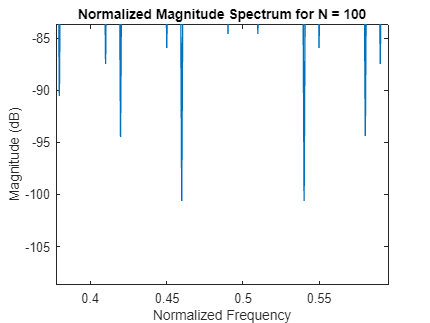

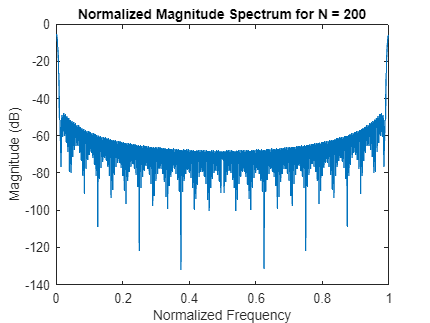

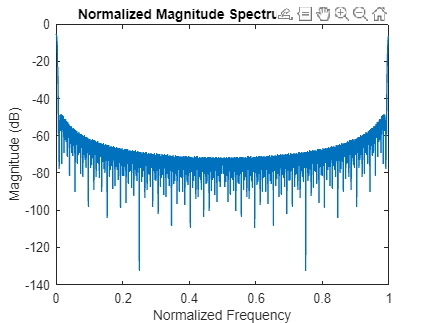

% DFT length
DFT_len = 1024;

% window lengths
window_lengths = [100, 200, 300];

% Loop 
for i = 1:length(window_lengths)
    
    hamming_window = hamming(window_lengths(i));
    
    % Zero pad the window to match the DFT length
    hamming_window_padded = [hamming_window; zeros(DFT_len - window_lengths(i), 1)];
    
    % Compute the DFT 
    hamming_window_DFT = fft(hamming_window_padded);
    
    % Normalize the magnitude of the DFT by the window length
    hamming_window_DFT_normalized = abs(hamming_window_DFT) / window_lengths(i);
    
    % frequency axis
    freq_axis = (0:(DFT_len - 1)) / DFT_len;
    
    % Plot the normalized magnitude spectrum
    figure;
    plot(freq_axis, 20 * log10(hamming_window_DFT_normalized));
    title(['Normalized Magnitude Spectrum for N = ', num2str(window_lengths(i))]);
    xlabel('Normalized Frequency');
    ylabel('Magnitude (dB)');
end

q2

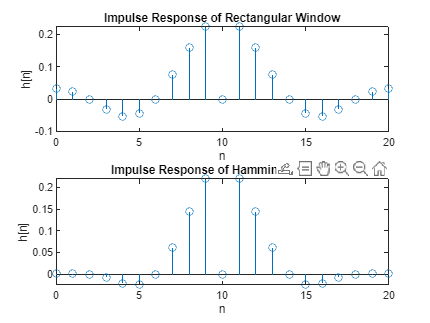

% Define the parameters
alpha = 3;
wc = pi / (alpha + 1); % Cut-off frequency
N = 21; % Window length

% Define the filter order
M = N - 1;

% Define the center of the window
center = M / 2;

% Generate the time vector
n = [0:M];

% Compute the sinc function for the ideal low pass filter
hd = sin(wc * (n - center)) ./ (pi * (n - center + eps)); % Add eps to avoid division by zero

% Apply the window functions
rectangular_window = rectwin(M+1);
hamming_window = hamming(M+1);

% Compute the filter coefficients
h_rectangular = hd .* rectangular_window';
h_hamming = hd .* hamming_window';

% Plot the impulse responses
figure;
subplot(2,1,1);
stem([0:M], h_rectangular);
title('Impulse Response of Rectangular Window');
xlabel('n');
ylabel('h[n]');

subplot(2,1,2);
stem([0:M], h_hamming);
title('Impulse Response of Hamming Window');
xlabel('n');
ylabel('h[n]');

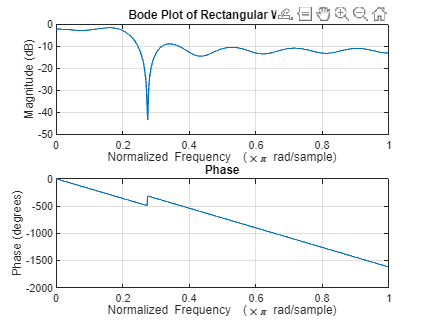


% Perform bode analysis
figure;
freqz(h_rectangular, 1);
title('Bode Plot of Rectangular Window');

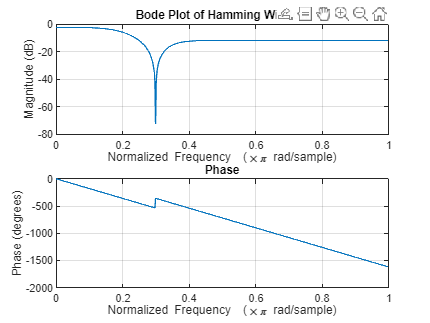


figure;
freqz(h_hamming, 1);
title('Bode Plot of Hamming Window');

q3

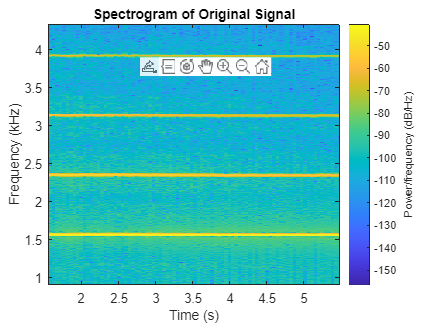

[x, Fs] = audioread('instru3.wav');

% Plot the spectrogram of the original signal
figure;
spectrogram(x, hamming(1024), 512, 1024, Fs, 'yaxis');
title('Spectrogram of Original Signal');

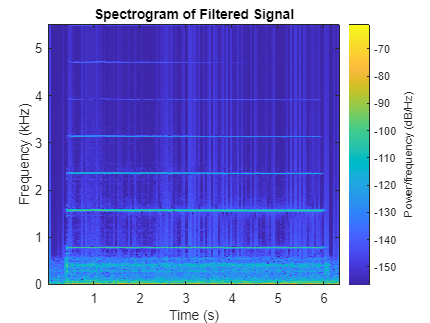


% Design a digital FIR filter to extract the fundamental frequency
% Here we assume that the fundamental frequency is below 500 Hz
% You may need to adjust this value based on your specific audio file
f_norm = 500 / (Fs / 2); % Normalized frequency
b = fir1(100, f_norm, 'low', hamming(101));

% Apply the filter to the signal
y = filter(b, 1, x);

% Write the filtered signal into a new .wav file
audiowrite('filtered_signal.wav', y, Fs);

% Plot the spectrogram of the filtered signal
figure;
spectrogram(y, hamming(1024), 512, 1024, Fs, 'yaxis');
title('Spectrogram of Filtered Signal');